##  Nuñez Peralta Yanet (202132131)

## Tarea 2

### Ejercicios del Libro Nieves

#### Ejercicio 2.8.

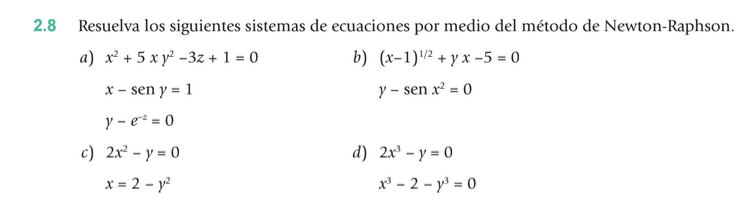

#### a)

% Función que define el sistema de ecuaciones
function F = sistema_ecuaciones(x)
    F = [x(1)^2 + 5*x(1)*x(2)^2 - 3*x(3)+1; x(1)-sen(x(2)) - 1; x(2)-exp^-x(3)];
end

% Función que calcula la matriz jacobiana del sistema
function J = jacobiana(x)
  J = [2*x(1), 2*x(2), 2*x(3);
         x(2), x(1) + x(3), x(2);
         x(3), 0, x(1)];
end

x0 = [1; 1; 1];  % Punto de inicio
tol = 1e-6;       % Tolerancia
max_iter = 100;   % Número máximo de iteraciones

[x, iter] = newton_raphson_sistema(@sistema_ecuaciones, @jacobiana, x0, tol, max_iter);

disp('Solución aproximada:');
disp(x);
disp(['Número de iteraciones: ', num2str(iter)]);


#### b)

% Función que define el sistema de ecuaciones
function F = sistema_ecuaciones(x)
    F = [(x(1)-1)^1/2 + x(2)*x(1)-5; x(2)-sen(x(1))^2];
end

% Función que calcula la matriz jacobiana del sistema
function J = jacobiana(x)
   J = [2*x(1), 2*x(2); x(2), x(1)];
end

x0 = [1; 1];  % Punto de inicio
tol = 1e-6;       % Tolerancia
max_iter = 100;   % Número máximo de iteraciones

[x, iter] = newton_raphson_sistema(@sistema_ecuaciones, @jacobiana, x0, tol, max_iter);

disp('Solución aproximada:');
disp(x);
disp(['Número de iteraciones: ', num2str(iter)]);


#### c)

% Función que define el sistema de ecuaciones
function F = sistema_ecuaciones(x)
    F = [2*x(1)^2-x(2); x(1)-2+x(2)^2];
end

% Función que calcula la matriz jacobiana del sistema
function J = jacobiana(x)
   J = [2*x(1), 2*x(2); x(2), x(1)];
end

x0 = [1; 1];  % Punto de inicio
tol = 1e-6;       % Tolerancia
max_iter = 100;   % Número máximo de iteraciones

[x, iter] = newton_raphson_sistema(@sistema_ecuaciones, @jacobiana, x0, tol, max_iter);

disp('Solución aproximada:');
disp(x);
disp(['Número de iteraciones: ', num2str(iter)]);


#### d)

% Función que define el sistema de ecuaciones
function F = sistema_ecuaciones(x)
    F = [2*x(3)^3-x(2); x(1)^3-2-x(2)^3];
end

% Función que calcula la matriz jacobiana del sistema
function J = jacobiana(x)
   J = [2*x(1), 2*x(2); x(2), x(1)];
end

x0 = [1; 1];  % Punto de inicio
tol = 1e-6;       % Tolerancia
max_iter = 100;   % Número máximo de iteraciones

[x, iter] = newton_raphson_sistema(@sistema_ecuaciones, @jacobiana, x0, tol, max_iter);

disp('Solución aproximada:');
disp(x);
disp(['Número de iteraciones: ', num2str(iter)]);


% Define la función de la ecuación
f = @(x) exp(x) - 2^(-x) + 2*cos(x) - 6;

% Puntos iniciales
x0 = 1;
x1 = 2;

% Tolerancia y número máximo de iteraciones
tol = 1e-6;
max_iter = 100;

% Resuelve la ecuación utilizando el método de la secante
[x, iter] = secante(f, x0, x1, tol, max_iter);

disp('Raíz aproximada:');
disp(x);
disp(['Número de iteraciones: ', num2str(iter)]);

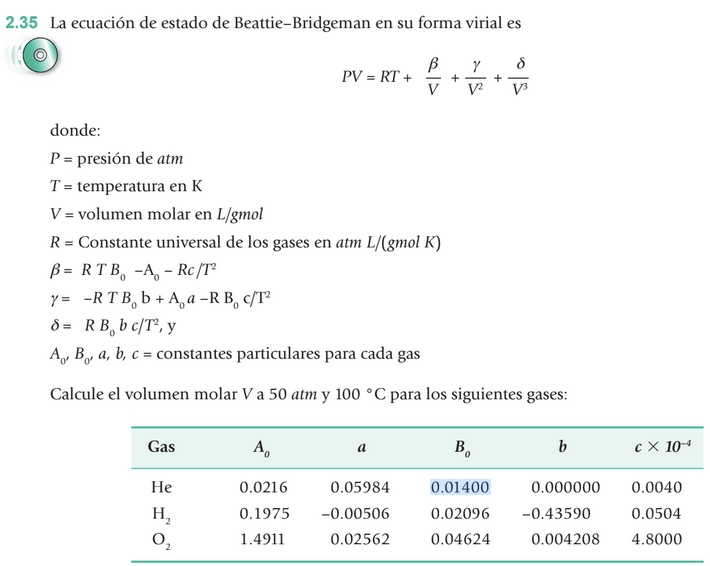

#### Helio

% Datos proporcionados
A0 = 0.0216;
a = 0.05984;
B0 = 0.01400;
b = 0;
c = 0.0040e-4;  % Convertir a metros por Kelvin

% Datos del problema
P = 50 * 1.01325e5;  % Convertir de atm a Pascal
T = 100 + 273.15;   % Convertir de Celsius a Kelvin

% Calcular coeficientes B(T) y C(T)
B_T = B0 - a * P;
C_T = A0 / T + c / T^3;

% Resolución de la ecuación de estado para V
syms V
eq = 1 + B_T / V + C_T / V^2 == P / (8.314 * T);
V_sol = solve(eq, V);

% Mostrar el resultado
disp(['El volumen molar a 50 atm y 100 °C es: ', num2str(V_sol), ' m^3/mol']);


#### Hidrogeno

% Datos proporcionados
A0 = 0.0216;
a = -0.00506;
B0 = 0.02096;
b = -0.43590;
c = 0.0504e-4;  % Convertir a metros por Kelvin

% Datos del problema
P = 50 * 1.01325e5;  % Convertir de atm a Pascal
T = 100 + 273.15;   % Convertir de Celsius a Kelvin

% Calcular coeficientes B(T) y C(T)
B_T = B0 - a * P;
C_T = A0 / T + c / T^3;

% Resolución de la ecuación de estado para V
syms V
eq = 1 + B_T / V + C_T / V^2 == P / (8.314 * T);
V_sol = solve(eq, V);

% Mostrar el resultado
disp(['El volumen molar a 50 atm y 100 °C es: ', num2str(V_sol), ' m^3/mol']);

#### Oxígeno

% Datos proporcionados
A0 = 1.4911;
a = 0.02562;
B0 = 0.04624;
b = 0.004208;
c = 4.8e-4;  % Convertir a metros por Kelvin

% Datos del problema
P = 50 * 1.01325e5;  % Convertir de atm a Pascal
T = 100 + 273.15;   % Convertir de Celsius a Kelvin

% Calcular coeficientes B(T) y C(T)
B_T = B0 - a * P;
C_T = A0 / T + c / T^3;

% Resolución de la ecuación de estado para V
syms V
eq = 1 + B_T / V + C_T / V^2 == P / (8.314 * T);
V_sol = solve(eq, V);

% Mostrar el resultado
disp(['El volumen molar a 50 atm y 100 °C es: ', num2str(V_sol), ' m^3/mol']);

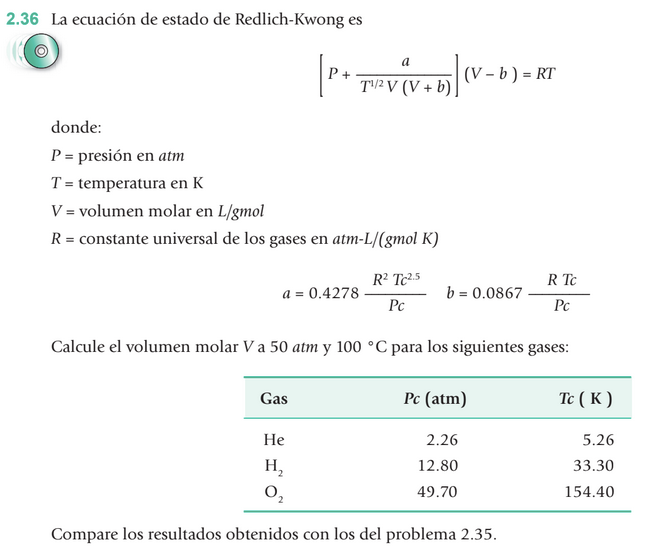

#### Helio

% Datos proporcionados
P = 50; % 50 atm
T = 100 + 273.15; % 100 °C a Kelvin
Pc = 2.26; % Presión crítica en atm
Tc = 5.26; % Temperatura crítica en Kelvin

% Constantes de los gases
R = 0.0821; % L·atm/(mol·K)

% Calcular constantes a y b
a = 0.427 * (R^2 * Tc^2 / Pc);
b = 0.0866 * (R * Tc / Pc);

% Calcular volumen molar utilizando la ecuación de estado de Redlich-Wong
Vm = (R * T) / (P + a / (Vm * (Vm + b)));

disp(['El volumen molar a 50 atm y 100 °C es: ', num2str(Vm), ' L/mol']);

#### Hidrogeno

% Datos proporcionados
P = 50; % 50 atm
T = 100 + 273.15; % 100 °C a Kelvin
Pc = 12.8; % Presión crítica en atm
Tc = 33.30; % Temperatura crítica en Kelvin

% Constantes de los gases
R = 0.0821; % L·atm/(mol·K)

% Calcular constantes a y b
a = 0.427 * (R^2 * Tc^2 / Pc);
b = 0.0866 * (R * Tc / Pc);

% Calcular volumen molar utilizando la ecuación de estado de Redlich-Wong
Vm = (R * T) / (P + a / (Vm * (Vm + b)));

disp(['El volumen molar a 50 atm y 100 °C es: ', num2str(Vm), ' L/mol']);

#### Oxígeno

% Datos proporcionados
P = 50; % 50 atm
T = 100 + 273.15; % 100 °C a Kelvin
Pc = 49.7; % Presión crítica en atm
Tc = 154.4; % Temperatura crítica en Kelvin

% Constantes de los gases
R = 0.0821; % L·atm/(mol·K)

% Calcular constantes a y b
a = 0.427 * (R^2 * Tc^2 / Pc);
b = 0.0866 * (R * Tc / Pc);

% Calcular volumen molar utilizando la ecuación de estado de Redlich-Wong
Vm = (R * T) / (P + a / (Vm * (Vm + b)));

disp(['El volumen molar a 50 atm y 100 °C es: ', num2str(Vm), ' L/mol']);


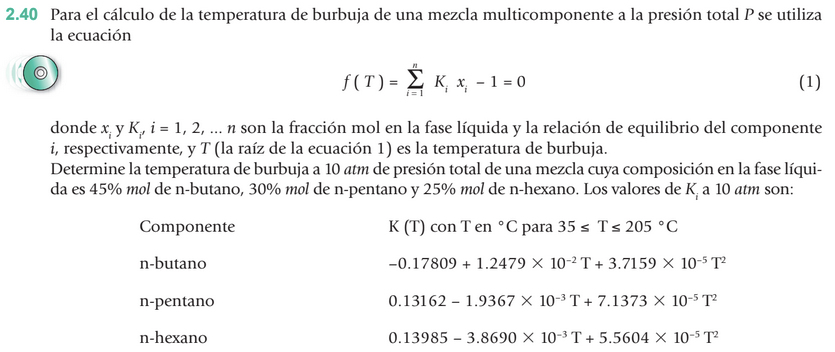

% Datos de la mezcla
P = 10; % Presión total en atm

% Composición en la fase líquida
x_butano = 0.45;
x_pentano = 0.30;
x_hexano = 0.25;

% Coeficientes Ki a 10 atm y sus ecuaciones
K_butano = @(T) -0.17809 + 1.2479e-2 * T + 3.7159e-5 * T^2;
K_pentano = @(T) 0.13162 - 1.9367e-3 * T + 7.1373e-5 * T^2;
K_hexano = @(T) 0.13985 - 3.8690e-3 * T + 5.5604e-5 * T^2;

% Función de equilibrio de fase f(T)
f = @(T) (K_butano(T) * x_butano + K_pentano(T) * x_pentano + K_hexano(T) * x_hexano) - 1;

% Derivada de f(T)
f_prime = @(T) (1.2479e-2 + 2 * 3.7159e-5 * T) * x_butano + (-1.9367e-3 + 2 * 7.1373e-5 * T) * x_pentano + (-3.8690e-3 + 2 * 5.5604e-5 * T) * x_hexano;

% Suponemos una temperatura inicial
T_guess = 100; % Por ejemplo, 100 °C

% Resolvemos la ecuación f(T) = 0 utilizando el método de Newton-Raphson
T_burbuja = fzero(f, T_guess);

disp(['La temperatura de burbuja a ', num2str(P), ' atm es: ', num2str(T_burbuja), ' °C']);


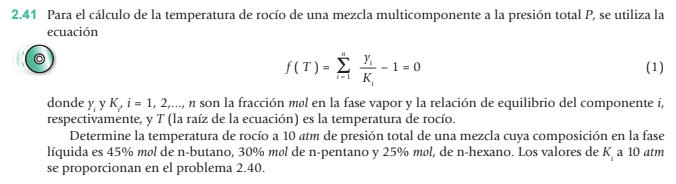

% Fracciones molares en la fase líquida
x1 = 0.45;  % Fracción mol de n-butano
x2 = 0.30;  % Fracción mol de n-pentano
x3 = 0.25;  % Fracción mol de n-hexano

function result = f(T, K)
    y = zeros(length(K), 1);
    
    % Calcular las fracciones molares en la fase vapor usando la relación de equilibrio Ki
    for i = 1:length(K)
        y(i) = K(i) * x(i);
    end
    
    % Calcular f(T)
    result = sum(y) - 1;
end

% Valores de Ki proporcionados en el problema 2.40 (asegúrate de tenerlos)
K1 = ...;  % Valor de K para n-butano a 10 atm
K2 = ...;  % Valor de K para n-pentano a 10 atm
K3 = ...;  % Valor de K para n-hexano a 10 atm

% Vector de valores Ki
K = [K1, K2, K3];

% Llamar a fminbnd para encontrar la temperatura de rocío
T_rocio = fminbnd(@(T) f(T, K), 0, 100);  % Intervalo de búsqueda [0, 100] grados Celsius (ajusta según sea necesario)

% Mostrar la temperatura de rocío
fprintf('La temperatura de rocío es %.2f grados Celsius.\n', T_rocio);